# **Newton's Interpolation**

**Let's assume y = 0.5e^(0.1x) + 2.     Let's plot this function from x = 0 to 40**

xx = 0:1:40;
yy = 0.5 * exp(0.1*xx) + 2

yy =     2.5000    2.5526    2.6107    2.6749    2.7459    2.8244    2.9111    3.0069    3.1128    3.2298    3.3591    3.5021    3.6601    3.8346    4.0276    4.2408    4.4765    4.7370    5.0248    5.3429    5.6945    6.0831    6.5125    6.9871    7.5116    8.0912    8.7319    9.4399   10.2223   11.0871   12.0428   13.0990   14.2663   15.5563   16.9821   18.5577   20.2991   22.2237   24.3506   26.7012   29.2991


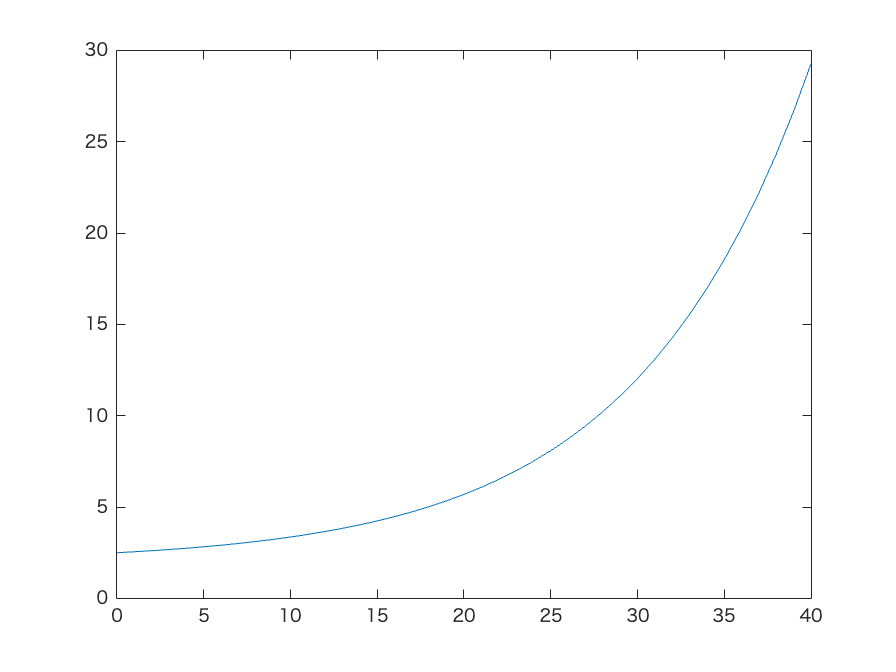


plot(xx, yy, '-')


poly_order_1 = polyfit(x, y, 1)

poly_order_1 =     0.1446   -0.2411


yy1 = polyval(poly_order_1, xx)

yy1 =    -0.2411   -0.0964    0.0482    0.1929    0.3375    0.4821    0.6268    0.7714    0.9161    1.0607    1.2054    1.3500    1.4946    1.6393    1.7839    1.9286    2.0732    2.2179    2.3625    2.5071    2.6518    2.7964    2.9411    3.0857    3.2304    3.3750    3.5196    3.6643    3.8089    3.9536    4.0982    4.2429    4.3875    4.5321    4.6768    4.8214    4.9661    5.1107    5.2554    5.4000    5.5446


**Now let's assume that we don't know this function, but we know only some points on this function.**

# Linear

**For example, if we only know 2 points with equal interval between 0 and 40, then we can use ****linear**** interpolation (a first-order Newton polynomial)  to predict the unknown function**

x = linspace(0, 40, 2)';
y = 0.5 * exp(0.1*x) + 2;

yy1_newt = Newtint(x, y, xx);

b =     2.5000    0.6700
   29.2991         0


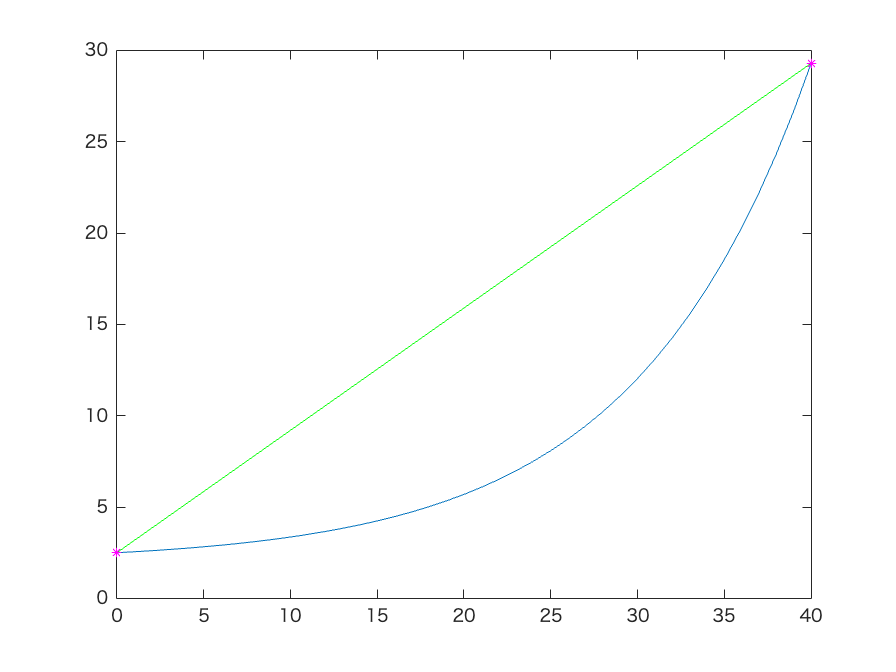

plot(xx, yy, '-')
hold on
plot(xx, yy1_newt, 'g-', x, y, 'm*')
hold off

ypred = Newtint(x, y, 12.5)

b =     2.5000    0.6700
   29.2991         0


ypred = 10.8747

# Quadratic

**Now assume that we only know 3 points with equal interval between 0 and 40, then we can use a polynomial interpolation (a 2-order Newton polynomial)  to predict the unknown function**

x = linspace(0, 40, 3)';
y = 0.5 * exp(0.1*x) + 2;

yy2_newt = Newtint(x, y, xx);

b =     2.5000    0.1597         0
    5.6945         0         0
   29.2991         0         0


b =     2.5000    0.1597         0
    5.6945    1.1802         0
   29.2991         0         0


b =     2.5000    0.1597    0.0255
    5.6945    1.1802         0
   29.2991         0         0


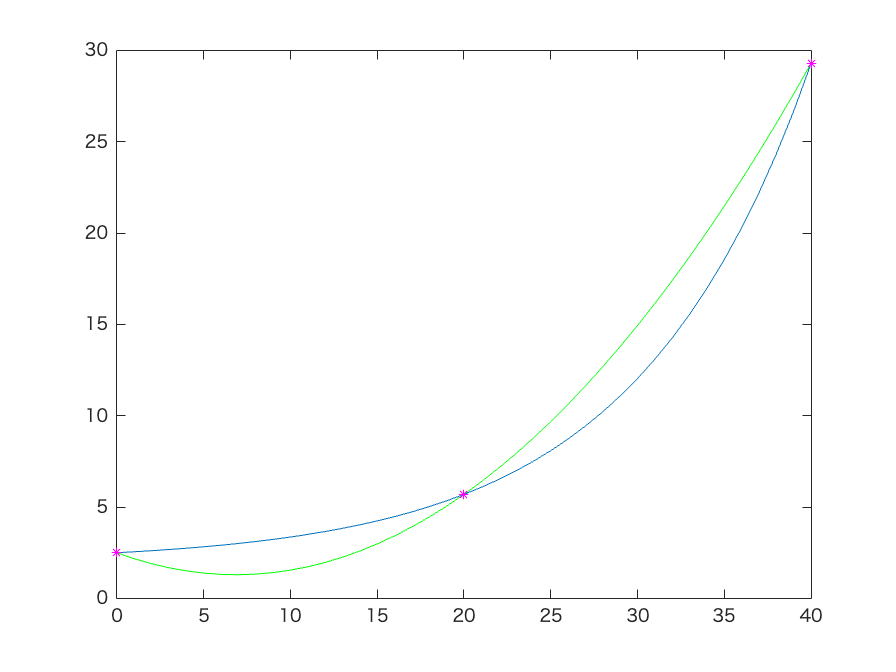

plot(xx, yy, '-')
hold on
plot(xx, yy2_newt, 'g-', x, y, 'm*')
hold off

# Cubic

**Now assume that we only know 4 points with equal interval between 0 and 40, then we can use a polynomial interpolation (a 3rd-order Newton polynomial) to predict the unknown function**

x = linspace(0, 40, 4)';
y = 0.5 * exp(0.1*x) + 2;

yy3_newt = Newtint(x, y, xx);

b =     2.5000    0.1048         0         0
    3.8968         0         0         0
    9.1960         0         0         0
   29.2991         0         0         0


b =     2.5000    0.1048         0         0
    3.8968    0.3974         0         0
    9.1960         0         0         0
   29.2991         0         0         0


b =     2.5000    0.1048         0         0
    3.8968    0.3974         0         0
    9.1960    1.5077         0         0
   29.2991         0         0         0


b =     2.5000    0.1048    0.0110         0
    3.8968    0.3974         0         0
    9.1960    1.5077         0         0
   29.2991         0         0         0


b =     2.5000    0.1048    0.0110         0
    3.8968    0.3974    0.0416         0
    9.1960    1.5077         0         0
   29.2991         0         0         0


b =     2.5000    0.1048    0.0110    0.0008
    3.8968    0.3974    0.0416         0
    9.1960    1.5077         0         0
   29.2991         0         0         0


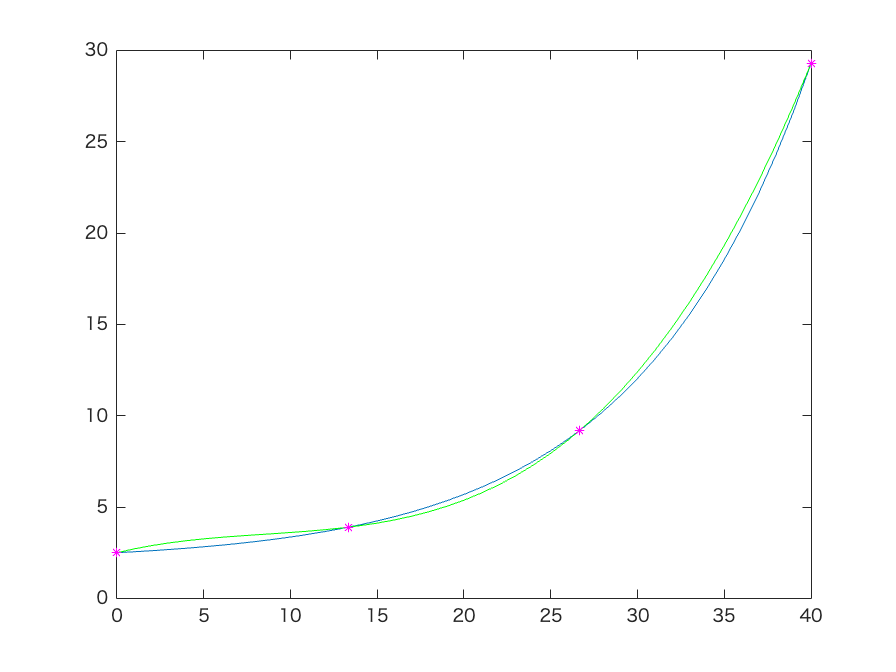

plot(xx, yy, '-')
hold on
plot(xx, yy3_newt, 'g-', x, y, 'm*')
hold off